## Plot data and external control signal

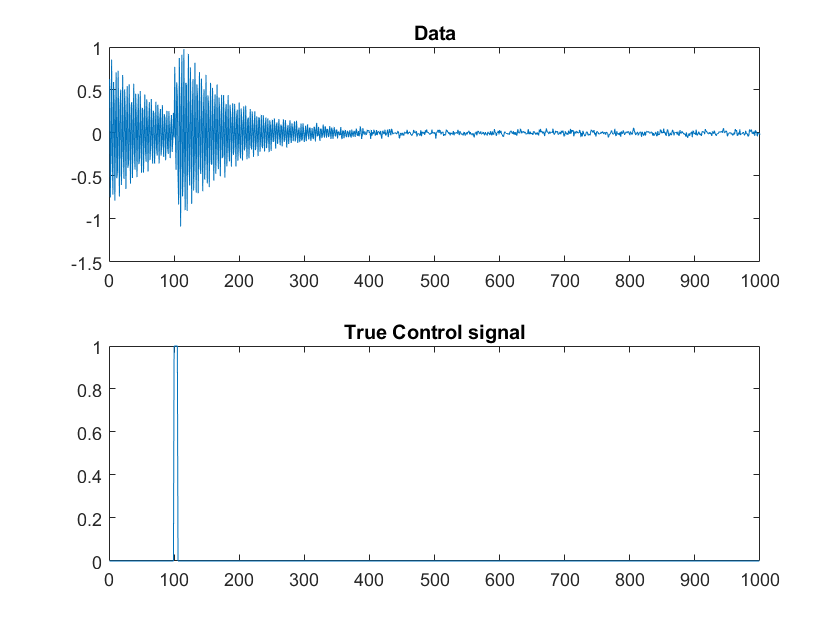

% Build example dynamics matrix
seed = 17;
n = 2;
m = 1000;
eigenvalue_min = 0.95;
[X_dmd, A] = test_dmd_dat(n, m, 0, eigenvalue_min, seed);

% Generate random controller
ctr_timing = 100:105;
U = zeros(1,m-1);
U(ctr_timing) = 1.0;

% Generate controlled data
x0 = X_dmd(:,1);
B = ones(n,1);
X_true = real(calc_reconstruction_dmd(x0, [], A, B, U));
% Add noise
noise = 0.02;
X = X_true + noise*randn(size(X_true));

% Plot
figure;

subplot(2,1,1)
plot(1:m,X(1,:))
title("Data")

subplot(2,1,2)
plot(1:m-1,U)
title("True Control signal")

## Do DMDc using the known control signal

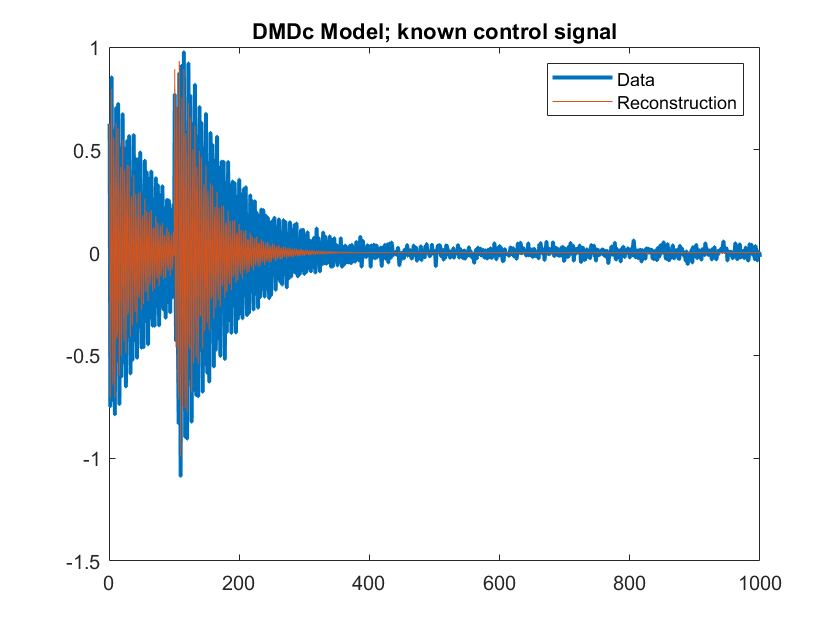

% Exact DMDc; uses L2 solution
[A, B, dat_reconstruction] = simple_dmdc(X, U);

% Plot Reconstruction along with data
figure;
plot(X(1,:), 'linewidth', 2)
hold on
plot(dat_reconstruction(1,:))
legend("Data", "Reconstruction")
title("DMDc Model; known control signal")

## Learn the control signal

% Returns a list of control signals with increasing sparsity
settings = struct('r_ctr',1, ... % Number of control signals to search for
                  'verbose',false, ... 
                   'num_iter',100); % Number of iterations
[all_U, all_A, all_B] =...
    learn_control_signals(X, settings);

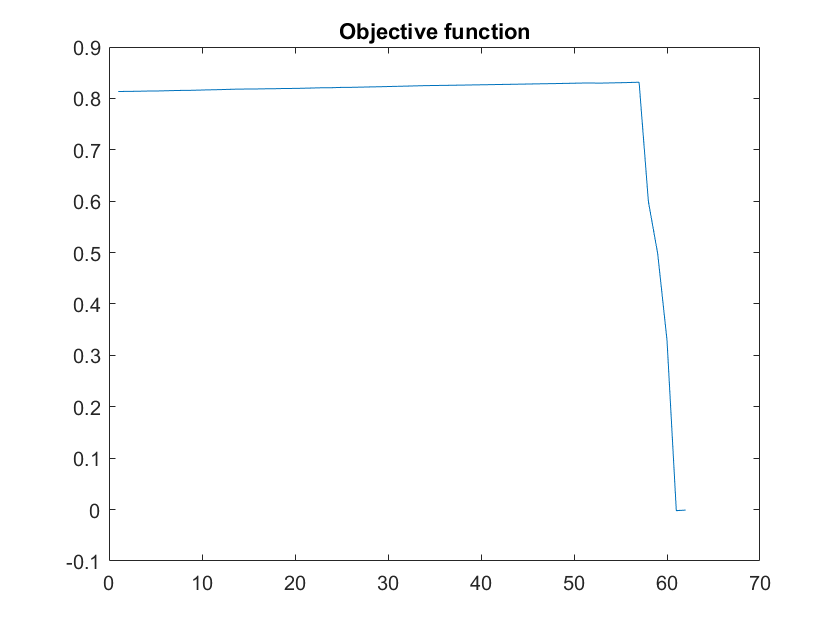


% Calculate some simple statistics about the control signal
all_nnz = zeros(size(all_U));
all_objective = all_nnz;
for i = 1:length(all_U)
    all_nnz(i) = nnz(all_U{i});
    all_objective(i) = acf(all_U{i}', 1, false);
end
all_objective(end) = all_objective(end-1);

% Get "best" signals and plot them
remove_ind = 20;

figure;
plot(all_objective(remove_ind:end))
title('Objective function')


[~, ind_best] = max(all_objective(remove_ind:end));
% ind_best = 63; warning("Custom best index")
best_U = all_U{ind_best+remove_ind-1};


% figure;
% plot(best_U);
% title(sprintf('Learned Signal (iteration %d)', ind_best))

## Plot Reconstruction using learned control signal

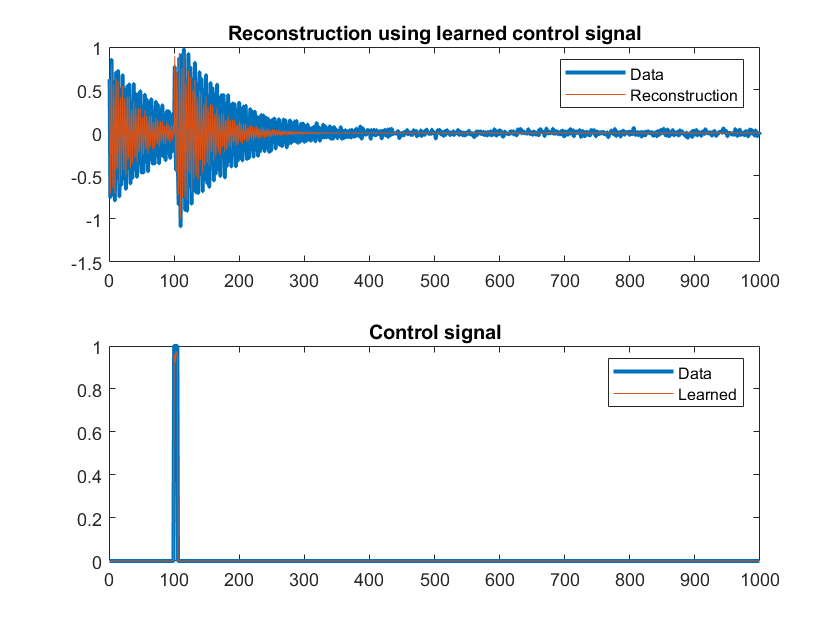

% Get learned matrices
% best_A = all_A{ind_best};
% best_B = all_B{ind_best};
[best_A, best_B, learned_X] = simple_dmdc(X, U);

% Initial condition
% x0 = X(:,1);

% Calculate reconstruction
% learned_X = calc_reconstruction_dmd(x0, [], best_A, best_B, best_U);

% Plot
figure;

subplot(2,1,1)
plot(X(1,:), 'linewidth', 2)
hold on
plot(learned_X(1,:))
legend("Data", "Reconstruction")
title("Reconstruction using learned control signal")

subplot(2,1,2)
plot(U, 'linewidth', 2)
hold on
plot(best_U)
legend("Data", "Learned")
title("Control signal")